wind_vectors = {wind1(:), wind2(:), wind3(:), wind4(:), wind5(:), wind6(:)};
wind_names = {'wind1', 'wind2', 'wind3', 'wind4', 'wind5', 'wind6'};
sun_vectors = {sun1(:), sun2(:), sun3(:), sun4(:)};
sun_names = {'sun1', 'sun2', 'sun3', 'sun4'};

classicload = classicload(:);
n = numel(wind_vectors{1});

% 目标：最大化 sum(t) = 最小化 -sum(t)，线性规划，使用 linprog
opts = optimoptions('linprog', 'Display', 'iter');
f  = -ones(n, 1);
lb = 0.1 * ones(n, 1);

problem4_results = struct([]);
result_idx = 0;

slack_vectors  = cell(numel(wind_vectors), numel(sun_vectors));
best_max_slack = -Inf;
best_wind_idx  = 1;
best_sun_idx   = 1;

for wind_idx = 1:numel(wind_vectors)
    wind = wind_vectors{wind_idx};
    for sun_idx = 1:numel(sun_vectors)
        sun = sun_vectors{sun_idx};

        raw_ub = (wind*40 + sun*64 - classicload*6) / (20.75*2);
        ub_val = min(ones(n,1), raw_ub);

        slack = zeros(n,1);
        for i = 1:n
            if ub_val(i) < 0.1
                slack(i) = ub_val(i) - 0.1;   % 缺电：负值
            elseif raw_ub(i) > 1
                slack(i) = raw_ub(i) - 1;      % 弃电：正值
            end
        end

        slack_vectors{wind_idx, sun_idx} = slack;
        fprintf('  %s + %s 弃电/缺电向量：\n', wind_names{wind_idx}, sun_names{sun_idx});
        fprintf('    ['); fprintf(' %8.4g', slack); fprintf(' ]\n');

        if max(slack) > best_max_slack
            best_max_slack = max(slack);
            best_wind_idx  = wind_idx;
            best_sun_idx   = sun_idx;
        end
    end
end

  wind1 + sun1 弃电/缺电向量：


    [        0        0        0        0        0        0        0  0.08515    0.228   0.3544   0.4521   0.4187   0.4847   0.6422   0.3387   0.2568        0        0        0 -0.01286 -0.05441 -0.05032    -0.02 -0.05875 ]


  wind1 + sun2 弃电/缺电向量：


    [        0        0        0        0        0        0        0        0        0        0        0        0        0   0.1795        0        0        0        0        0 -0.01286 -0.05441 -0.05032    -0.02 -0.05875 ]


  wind1 + sun3 弃电/缺电向量：


    [        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0 -0.01286 -0.05441 -0.05032    -0.02 -0.05875 ]


  wind1 + sun4 弃电/缺电向量：


    [        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0 -0.02183   -0.008 -0.01286 -0.05441 -0.05032    -0.02 -0.05875 ]


  wind2 + sun1 弃电/缺电向量：


    [ -0.005007        0        0        0        0        0        0        0        0   0.1263   0.2939   0.3357    0.379   0.4559   0.3787     0.19        0        0        0 -0.04718 -0.08872  -0.1033 -0.08641 -0.04661 ]


  wind2 + sun2 弃电/缺电向量：


    [ -0.005007        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0 -0.04718 -0.08872  -0.1033 -0.08641 -0.04661 ]


  wind2 + sun3 弃电/缺电向量：


    [ -0.005007        0        0        0        0        0        0        0 -0.005104        0        0        0        0        0        0        0        0        0        0 -0.04718 -0.08872  -0.1033 -0.08641 -0.04661 ]


  wind2 + sun4 弃电/缺电向量：


    [ -0.005007        0        0        0        0        0        0        0 -0.08221  -0.0841  -0.0707 -0.05971        0        0        0        0 -0.04829 -0.01643 -0.01224 -0.04718 -0.08872  -0.1033 -0.08641 -0.04661 ]


  wind3 + sun1 弃电/缺电向量：


    [        0        0        0        0        0        0        0        0  0.05596   0.2963   0.3774   0.4564   0.4957   0.5502   0.4326   0.3381  0.04227        0        0        0        0        0        0        0 ]


  wind3 + sun2 弃电/缺电向量：


    [        0        0        0        0        0        0        0        0        0        0        0        0 0.002222  0.08757        0        0        0        0        0        0        0        0        0        0 ]


  wind3 + sun3 弃电/缺电向量：


    [        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0 ]


  wind3 + sun4 弃电/缺电向量：


    [        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0 ]


  wind4 + sun1 弃电/缺电向量：


    [        0        0        0        0        0        0        0   0.1708   0.4021    0.542   0.3821   0.4167   0.5392   0.5562   0.5422   0.5094   0.1251        0        0        0        0  -0.0136        0        0 ]


  wind4 + sun2 弃电/缺电向量：


    [        0        0        0        0        0        0        0        0        0        0        0        0  0.04569  0.09355  0.04872  0.04674        0        0        0        0        0  -0.0136        0        0 ]


  wind4 + sun3 弃电/缺电向量：


    [        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0  -0.0136        0        0 ]


  wind4 + sun4 弃电/缺电向量：


    [        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0  -0.0136        0        0 ]


  wind5 + sun1 弃电/缺电向量：


    [        0        0        0        0        0        0        0        0   0.3358   0.5134   0.5507   0.5775   0.5855    0.601    0.376   0.1936  0.08901        0        0        0        0        0        0        0 ]


  wind5 + sun2 弃电/缺电向量：


    [        0        0        0        0        0        0        0        0        0        0        0  0.00694  0.09205   0.1384        0        0        0        0        0        0        0        0        0        0 ]


  wind5 + sun3 弃电/缺电向量：


    [        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0 ]


  wind5 + sun4 弃电/缺电向量：


    [        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0 ]


  wind6 + sun1 弃电/缺电向量：


    [        0        0        0        0        0        0        0        0   0.0309   0.1766   0.3108   0.3783   0.4359   0.4313    0.308   0.1168        0        0        0        0        0        0        0        0 ]


  wind6 + sun2 弃电/缺电向量：


    [        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0 ]


  wind6 + sun3 弃电/缺电向量：


    [        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0        0 ]


  wind6 + sun4 弃电/缺电向量：


    [        0        0        0        0        0        0        0        0        0 -0.03378 -0.05374 -0.01711        0        0        0 -0.03186 -0.02998        0        0        0        0        0        0        0 ]



fprintf('最大弃电场景：%s + %s（最大弃电量 = %.4g）\n', ...
        wind_names{best_wind_idx}, sun_names{best_sun_idx}, best_max_slack);

最大弃电场景：wind1 + sun1（最大弃电量 = 0.6422）




for wind_idx = 1:numel(wind_vectors)
    wind = wind_vectors{wind_idx};
    wind_name = wind_names{wind_idx};

    for sun_idx = 1:numel(sun_vectors)
        sun = sun_vectors{sun_idx};
        sun_name = sun_names{sun_idx};

        fprintf('\n==================== 情况 %02d：%s + %s ====================\n', ...
                (wind_idx - 1)*numel(sun_vectors) + sun_idx, wind_name, sun_name);

        % 约束 load <= generate：t*41.5 <= wind*40+sun*64 - classicload*6
        % 等价于收紧各时段上界
        ub = min(ones(n,1), (wind*40 + sun*64 - classicload*6) / (20.75*2));

        if any(ub < lb)
            warning('%s + %s：部分时段发电量不足以支撑最低制氢负荷，跳过。', wind_name, sun_name);
            continue;
        end

        t_opt = linprog(f, [], [], [], [], lb, ub, opts);
        t_opt = t_opt(:);
        sum_t = sum(t_opt);
        fprintf('最大 sum(t) = %.6g\n', sum_t);
        disp('最优 t 向量：'); disp(t_opt);


        J = objFun(t_opt, wind, sun);
        fprintf('目标函数 J = %.6g\n', J);

        result_idx = result_idx + 1;
        problem4_results(result_idx).case_idx    = result_idx;
        problem4_results(result_idx).wind_idx    = wind_idx;
        problem4_results(result_idx).wind_name   = wind_name;
        problem4_results(result_idx).sun_idx     = sun_idx;
        problem4_results(result_idx).sun_name    = sun_name;
        problem4_results(result_idx).t_opt       = t_opt;
        problem4_results(result_idx).sum_t       = sum_t;
        % ---------------- 新增：年产量与利用率指标 ----------------
        % 制氢氨满载等效功率 (MW)：碱性10 + PEM10 + 合成氨0.75 = 20.75，产能扩容2倍 → 41.5
        P_h2_total      = 20.75 * 2;
        annual_nh3      = sum_t * 3 * 365;                    % 全年制氨总量 (吨)
                                                              %   3 = 1.5吨/h × 1h步长 × 2倍扩容
        cap_utilization = sum_t / n;                          % 氢氨年平均产能利用率 = mean(t)
        gen_sum         = sum(wind*40 + sun*64);              % 日发电总量 (MW·h)
        power_util      = sum_t * P_h2_total / gen_sum;       % 发电利用率：制氨耗电 / 风光发电

        problem4_results(result_idx).annual_nh3      = annual_nh3;
        problem4_results(result_idx).cap_utilization = cap_utilization;
        problem4_results(result_idx).power_util      = power_util;
        problem4_results(result_idx).gen_sum         = gen_sum;

        fprintf('  全年制氨总量    = %.2f 吨\n', annual_nh3);
        fprintf('  产能利用率      = %.4f\n',    cap_utilization);
        fprintf('  发电利用率      = %.4f\n',    power_util);
    end
end


==================== 情况 01：wind1 + sun1 ====================



==================== 情况 02：wind1 + sun2 ====================



==================== 情况 03：wind1 + sun3 ====================



==================== 情况 04：wind1 + sun4 ====================



==================== 情况 05：wind2 + sun1 ====================



==================== 情况 06：wind2 + sun2 ====================



==================== 情况 07：wind2 + sun3 ====================



==================== 情况 08：wind2 + sun4 ====================



==================== 情况 09：wind3 + sun1 ====================


Running HiGHS 1.11.0: Copyright (c) 2025 HiGHS under MIT licence terms
Model has either no columns or no rows, so ignoring user constraint matrix data and initialising empty matrix
LP   has 0 rows; 24 cols; 0 nonzeros
Coefficient ranges:
  Cost   [1e+00, 1e+00]
  Bound  [1e-01, 1e+00]
Solving LP without presolve, or with basis, or unconstrained
Solving an unconstrained LP with 24 columns
Model status        : Optimal
Objective value     : -1.4307272289e+01
P-D objective error :  0.0000000000e+00
HiGHS run time      :          0.01

找到最优解。



最大 sum(t) = 14.3073


最优 t 向量：
    0.2538
    0.2960
    0.3245
    0.3549
    0.3351
    0.2854
    0.6123
    0.8431
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.8079
    0.5075
    0.1715
    0.1293
    0.1114
    0.1179
    0.1564



目标函数 J = 4117.01


  全年制氨总量    = 15666.46 吨


  产能利用率      = 0.5961


  发电利用率      = 0.7604



==================== 情况 10：wind3 + sun2 ====================


Running HiGHS 1.11.0: Copyright (c) 2025 HiGHS under MIT licence terms
Model has either no columns or no rows, so ignoring user constraint matrix data and initialising empty matrix
LP   has 0 rows; 24 cols; 0 nonzeros
Coefficient ranges:
  Cost   [1e+00, 1e+00]
  Bound  [1e-01, 1e+00]
Solving LP without presolve, or with basis, or unconstrained
Solving an unconstrained LP with 24 columns
Model status        : Optimal
Objective value     : -1.1032134940e+01
P-D objective error :  0.0000000000e+00
HiGHS run time      :          0.01

找到最优解。



最大 sum(t) = 11.0321


最优 t 向量：
    0.2538
    0.2960
    0.3245
    0.3549
    0.3351
    0.2854
    0.2731
    0.3034
    0.4237
    0.6177
    0.7143
    0.8858
    1.0000
    1.0000
    0.9391
    0.8755
    0.7030
    0.4532
    0.3070
    0.1715
    0.1293
    0.1114
    0.1179
    0.1564



目标函数 J = 3906.68


  全年制氨总量    = 12080.19 吨


  产能利用率      = 0.4597


  发电利用率      = 0.8766



==================== 情况 11：wind3 + sun3 ====================


Running HiGHS 1.11.0: Copyright (c) 2025 HiGHS under MIT licence terms
Model has either no columns or no rows, so ignoring user constraint matrix data and initialising empty matrix
LP   has 0 rows; 24 cols; 0 nonzeros
Coefficient ranges:
  Cost   [1e+00, 1e+00]
  Bound  [1e-01, 5e-01]
Solving LP without presolve, or with basis, or unconstrained
Solving an unconstrained LP with 24 columns
Model status        : Optimal
Objective value     : -7.1277108434e+00
P-D objective error :  0.0000000000e+00
HiGHS run time      :          0.01

找到最优解。



最大 sum(t) = 7.12771


最优 t 向量：
    0.2538
    0.2960
    0.3245
    0.3549
    0.3351
    0.2854
    0.2731
    0.2571
    0.2386
    0.3093
    0.2979
    0.4077
    0.4779
    0.5324
    0.4456
    0.4282
    0.3637
    0.2990
    0.2608
    0.1715
    0.1293
    0.1114
    0.1179
    0.1564



目标函数 J = 4202.94


  全年制氨总量    = 7804.84 吨


  产能利用率      = 0.2970


  发电利用率      = 0.8297



==================== 情况 12：wind3 + sun4 ====================


Running HiGHS 1.11.0: Copyright (c) 2025 HiGHS under MIT licence terms
Model has either no columns or no rows, so ignoring user constraint matrix data and initialising empty matrix
LP   has 0 rows; 24 cols; 0 nonzeros
Coefficient ranges:
  Cost   [1e+00, 1e+00]
  Bound  [1e-01, 4e-01]
Solving LP without presolve, or with basis, or unconstrained
Solving an unconstrained LP with 24 columns
Model status        : Optimal
Objective value     : -5.5701204819e+00
P-D objective error :  0.0000000000e+00
HiGHS run time      :          0.01

找到最优解。



最大 sum(t) = 5.57012


最优 t 向量：
    0.2538
    0.2960
    0.3245
    0.3549
    0.3351
    0.2854
    0.2731
    0.2263
    0.1615
    0.1859
    0.1129
    0.1610
    0.2620
    0.3782
    0.2914
    0.2894
    0.2403
    0.2219
    0.2299
    0.1715
    0.1293
    0.1114
    0.1179
    0.1564



目标函数 J = 4447.69


  全年制氨总量    = 6099.28 吨


  产能利用率      = 0.2321


  发电利用率      = 0.7920



==================== 情况 13：wind4 + sun1 ====================



==================== 情况 14：wind4 + sun2 ====================



==================== 情况 15：wind4 + sun3 ====================



==================== 情况 16：wind4 + sun4 ====================



==================== 情况 17：wind5 + sun1 ====================


Running HiGHS 1.11.0: Copyright (c) 2025 HiGHS under MIT licence terms
Model has either no columns or no rows, so ignoring user constraint matrix data and initialising empty matrix
LP   has 0 rows; 24 cols; 0 nonzeros
Coefficient ranges:
  Cost   [1e+00, 1e+00]
  Bound  [1e-01, 1e+00]
Solving LP without presolve, or with basis, or unconstrained
Solving an unconstrained LP with 24 columns
Model status        : Optimal
Objective value     : -1.4459175904e+01
P-D objective error :  0.0000000000e+00
HiGHS run time      :          0.10

找到最优解。



最大 sum(t) = 14.4592


最优 t 向量：
    0.2026
    0.2988
    0.3516
    0.2969
    0.3365
    0.3057
    0.7092
    0.7677
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.7121
    0.4044
    0.2182
    0.1933
    0.1781
    0.1119
    0.3722



目标函数 J = 4224.69


  全年制氨总量    = 15832.80 吨


  产能利用率      = 0.6025


  发电利用率      = 0.7323



==================== 情况 18：wind5 + sun2 ====================


Running HiGHS 1.11.0: Copyright (c) 2025 HiGHS under MIT licence terms
Model has either no columns or no rows, so ignoring user constraint matrix data and initialising empty matrix
LP   has 0 rows; 24 cols; 0 nonzeros
Coefficient ranges:
  Cost   [1e+00, 1e+00]
  Bound  [1e-01, 1e+00]
Solving LP without presolve, or with basis, or unconstrained
Solving an unconstrained LP with 24 columns
Model status        : Optimal
Objective value     : -1.1814207229e+01
P-D objective error :  0.0000000000e+00
HiGHS run time      :          0.01

找到最优解。



最大 sum(t) = 11.8142


最优 t 向量：
    0.2026
    0.2988
    0.3516
    0.2969
    0.3365
    0.3057
    0.3699
    0.2279
    0.7035
    0.8349
    0.8876
    1.0000
    1.0000
    1.0000
    0.8826
    0.7310
    0.7497
    0.3574
    0.2039
    0.2182
    0.1933
    0.1781
    0.1119
    0.3722



目标函数 J = 3921.74


  全年制氨总量    = 12936.56 吨


  产能利用率      = 0.4923


  发电利用率      = 0.8742



==================== 情况 19：wind5 + sun3 ====================


Running HiGHS 1.11.0: Copyright (c) 2025 HiGHS under MIT licence terms
Model has either no columns or no rows, so ignoring user constraint matrix data and initialising empty matrix
LP   has 0 rows; 24 cols; 0 nonzeros
Coefficient ranges:
  Cost   [1e+00, 1e+00]
  Bound  [1e-01, 6e-01]
Solving LP without presolve, or with basis, or unconstrained
Solving an unconstrained LP with 24 columns
Model status        : Optimal
Objective value     : -8.0573493976e+00
P-D objective error :  0.0000000000e+00
HiGHS run time      :          0.01

找到最优解。



最大 sum(t) = 8.05735


最优 t 向量：
    0.2026
    0.2988
    0.3516
    0.2969
    0.3365
    0.3057
    0.3699
    0.1816
    0.5184
    0.5265
    0.4712
    0.5289
    0.5677
    0.5832
    0.3891
    0.2838
    0.4105
    0.2032
    0.1576
    0.2182
    0.1933
    0.1781
    0.1119
    0.3722



目标函数 J = 4149.83


  全年制氨总量    = 8822.80 吨


  产能利用率      = 0.3357


  发电利用率      = 0.8463



==================== 情况 20：wind5 + sun4 ====================


Running HiGHS 1.11.0: Copyright (c) 2025 HiGHS under MIT licence terms
Model has either no columns or no rows, so ignoring user constraint matrix data and initialising empty matrix
LP   has 0 rows; 24 cols; 0 nonzeros
Coefficient ranges:
  Cost   [1e+00, 1e+00]
  Bound  [1e-01, 4e-01]
Solving LP without presolve, or with basis, or unconstrained
Solving an unconstrained LP with 24 columns
Model status        : Optimal
Objective value     : -6.4997590361e+00
P-D objective error :  0.0000000000e+00
HiGHS run time      :          0.01

找到最优解。



最大 sum(t) = 6.49976


最优 t 向量：
    0.2026
    0.2988
    0.3516
    0.2969
    0.3365
    0.3057
    0.3699
    0.1508
    0.4413
    0.4031
    0.2862
    0.2821
    0.3518
    0.4290
    0.2348
    0.1450
    0.2871
    0.1261
    0.1268
    0.2182
    0.1933
    0.1781
    0.1119
    0.3722



目标函数 J = 4346.86


  全年制氨总量    = 7117.24 吨


  产能利用率      = 0.2708


  发电利用率      = 0.8163



==================== 情况 21：wind6 + sun1 ====================


Running HiGHS 1.11.0: Copyright (c) 2025 HiGHS under MIT licence terms
Model has either no columns or no rows, so ignoring user constraint matrix data and initialising empty matrix
LP   has 0 rows; 24 cols; 0 nonzeros
Coefficient ranges:
  Cost   [1e+00, 1e+00]
  Bound  [1e-01, 1e+00]
Solving LP without presolve, or with basis, or unconstrained
Solving an unconstrained LP with 24 columns
Model status        : Optimal
Objective value     : -1.3595513253e+01
P-D objective error :  0.0000000000e+00
HiGHS run time      :          0.01

找到最优解。



最大 sum(t) = 13.5955


最优 t 向量：
    0.1947
    0.2266
    0.2648
    0.2533
    0.2405
    0.2249
    0.5379
    0.7848
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.8720
    0.7130
    0.4751
    0.1803
    0.1198
    0.1627
    0.1477
    0.1974



目标函数 J = 4005.9


  全年制氨总量    = 14887.09 吨


  产能利用率      = 0.5665


  发电利用率      = 0.7883



==================== 情况 22：wind6 + sun2 ====================


Running HiGHS 1.11.0: Copyright (c) 2025 HiGHS under MIT licence terms
Model has either no columns or no rows, so ignoring user constraint matrix data and initialising empty matrix
LP   has 0 rows; 24 cols; 0 nonzeros
Coefficient ranges:
  Cost   [1e+00, 1e+00]
  Bound  [1e-01, 1e+00]
Solving LP without presolve, or with basis, or unconstrained
Solving an unconstrained LP with 24 columns
Model status        : Optimal
Objective value     : -9.5537349398e+00
P-D objective error :  0.0000000000e+00
HiGHS run time      :          0.01

找到最优解。



最大 sum(t) = 9.55373


最优 t 向量：
    0.1947
    0.2266
    0.2648
    0.2533
    0.2405
    0.2249
    0.1986
    0.2451
    0.3986
    0.4980
    0.6477
    0.8077
    0.9424
    0.9686
    0.8145
    0.6542
    0.5327
    0.3583
    0.2747
    0.1803
    0.1198
    0.1627
    0.1477
    0.1974



目标函数 J = 3912.56


  全年制氨总量    = 10461.34 吨


  产能利用率      = 0.3981


  发电利用率      = 0.8672



==================== 情况 23：wind6 + sun3 ====================


Running HiGHS 1.11.0: Copyright (c) 2025 HiGHS under MIT licence terms
Model has either no columns or no rows, so ignoring user constraint matrix data and initialising empty matrix
LP   has 0 rows; 24 cols; 0 nonzeros
Coefficient ranges:
  Cost   [1e+00, 1e+00]
  Bound  [1e-01, 4e-01]
Solving LP without presolve, or with basis, or unconstrained
Solving an unconstrained LP with 24 columns
Model status        : Optimal
Objective value     : -5.5595180723e+00
P-D objective error :  0.0000000000e+00
HiGHS run time      :          0.01

找到最优解。



最大 sum(t) = 5.55952


最优 t 向量：
    0.1947
    0.2266
    0.2648
    0.2533
    0.2405
    0.2249
    0.1986
    0.1988
    0.2135
    0.1896
    0.2313
    0.3296
    0.4180
    0.4135
    0.3210
    0.2069
    0.1934
    0.2041
    0.2284
    0.1803
    0.1198
    0.1627
    0.1477
    0.1974



目标函数 J = 4332.77


  全年制氨总量    = 6087.67 吨


  产能利用率      = 0.2316


  发电利用率      = 0.7917



==================== 情况 24：wind6 + sun4 ====================


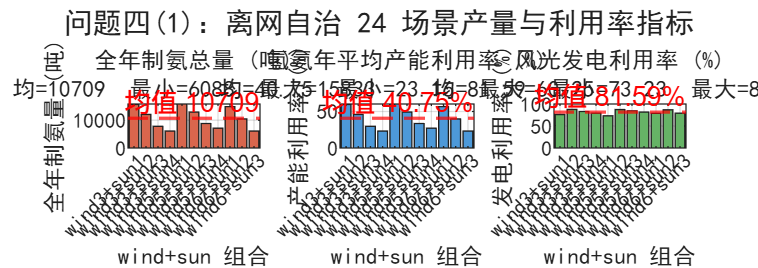



% =========================================================================
% problem4-1 补充图：年产量与产能/发电利用率分布
% =========================================================================
sort_keys = [[problem4_results.wind_idx]', [problem4_results.sun_idx]'];
[~, p1_order] = sortrows(sort_keys, [1 2]);
p1_sorted = problem4_results(p1_order);
combo_labels_p1 = arrayfun(@(r) sprintf('%s+%s', r.wind_name, r.sun_name), ...
                           p1_sorted, 'UniformOutput', false);

annual_vals = [p1_sorted.annual_nh3];
cap_vals    = [p1_sorted.cap_utilization];
power_vals  = [p1_sorted.power_util];

figure('Name', 'problem4-1：年产量与利用率分布', 'Color', 'w', ...
       'Position', [80 80 1300 460]);

subplot(1, 3, 1);
bar(annual_vals, 'FaceColor', [0.85 0.4 0.3]); grid on; hold on;
yline(mean(annual_vals), 'r--', sprintf('均值 %.0f', mean(annual_vals)), 'LineWidth', 1.2);
title(sprintf('全年制氨总量 (吨)\n均=%.0f  最小=%.0f  最大=%.0f', ...
      mean(annual_vals), min(annual_vals), max(annual_vals)));
xlabel('wind+sun 组合'); ylabel('全年制氨量 (吨)');
set(gca, 'XTick', 1:numel(combo_labels_p1), 'XTickLabel', combo_labels_p1, ...
         'XTickLabelRotation', 45);
xlim([0.5, numel(combo_labels_p1)+0.5]);

subplot(1, 3, 2);
bar(cap_vals*100, 'FaceColor', [0.3 0.6 0.85]); grid on; hold on;
yline(mean(cap_vals)*100, 'r--', sprintf('均值 %.2f%%', mean(cap_vals)*100), 'LineWidth', 1.2);
title(sprintf('氢氨年平均产能利用率 (%%)\n均=%.2f  最小=%.2f  最大=%.2f', ...
      mean(cap_vals)*100, min(cap_vals)*100, max(cap_vals)*100));
xlabel('wind+sun 组合'); ylabel('产能利用率 (%)');
set(gca, 'XTick', 1:numel(combo_labels_p1), 'XTickLabel', combo_labels_p1, ...
         'XTickLabelRotation', 45);
xlim([0.5, numel(combo_labels_p1)+0.5]);

subplot(1, 3, 3);
bar(power_vals*100, 'FaceColor', [0.4 0.7 0.4]); grid on; hold on;
yline(mean(power_vals)*100, 'r--', sprintf('均值 %.2f%%', mean(power_vals)*100), 'LineWidth', 1.2);
title(sprintf('风光发电利用率 (%%)\n均=%.2f  最小=%.2f  最大=%.2f', ...
      mean(power_vals)*100, min(power_vals)*100, max(power_vals)*100));
xlabel('wind+sun 组合'); ylabel('发电利用率 (%)');
set(gca, 'XTick', 1:numel(combo_labels_p1), 'XTickLabel', combo_labels_p1, ...
         'XTickLabelRotation', 45);
xlim([0.5, numel(combo_labels_p1)+0.5]);

sgtitle('问题四(1)：离网自治 24 场景产量与利用率指标');


% -------------------------------------------------------------------------
% 风光最小装机容量分析
% -------------------------------------------------------------------------
fprintf('\n\n==================== 风光最小装机容量分析 ====================\n');



==================== 风光最小装机容量分析 ====================


capacity_results = struct([]);
cap_idx = 0;

for wind_idx = 1:numel(wind_vectors)
    wind = wind_vectors{wind_idx};
    wind_name = wind_names{wind_idx};
    for sun_idx = 1:numel(sun_vectors)
        sun = sun_vectors{sun_idx};
        sun_name = sun_names{sun_idx};

        [Cw_min, Cs_min] = calcMinCapacity(wind, sun, classicload);

        cap_idx = cap_idx + 1;
        capacity_results(cap_idx).wind_name = wind_name;
        capacity_results(cap_idx).sun_name  = sun_name;
        capacity_results(cap_idx).wind_idx  = wind_idx;
        capacity_results(cap_idx).sun_idx   = sun_idx;
        capacity_results(cap_idx).Cw_min    = Cw_min;
        capacity_results(cap_idx).Cs_min    = Cs_min;

        fprintf('%-8s + %-6s：最小风电装机 Cw = %.4g MW，最小光电装机 Cs = %.4g MW\n', ...
                wind_name, sun_name, Cw_min, Cs_min);
    end
end

wind1    + sun1  ：最小风电装机 Cw = 70.55 MW，最小光电装机 Cs = 0 MW
wind1    + sun2  ：最小风电装机 Cw = 70.55 MW，最小光电装机 Cs = 0 MW
wind1    + sun3  ：最小风电装机 Cw = 70.55 MW，最小光电装机 Cs = 0 MW
wind1    + sun4  ：最小风电装机 Cw = 70.55 MW，最小光电装机 Cs = 0 MW
wind2    + sun1  ：最小风电装机 Cw = 155 MW，最小光电装机 Cs = 0 MW
wind2    + sun2  ：最小风电装机 Cw = 155 MW，最小光电装机 Cs = 0 MW
wind2    + sun3  ：最小风电装机 Cw = 155 MW，最小光电装机 Cs = 0 MW
wind2    + sun4  ：最小风电装机 Cw = 155 MW，最小光电装机 Cs = 0 MW
wind3    + sun1  ：最小风电装机 Cw = 36.98 MW，最小光电装机 Cs = 0.1592 MW
wind3    + sun2  ：最小风电装机 Cw = 36.98 MW，最小光电装机 Cs = 0.3348 MW
wind3    + sun3  ：最小风电装机 Cw = 37.57 MW，最小光电装机 Cs = 0 MW
wind3    + sun4  ：最小风电装机 Cw = 37.57 MW，最小光电装机 Cs = 0 MW
wind4    + sun1  ：最小风电装机 Cw = 44.33 MW，最小光电装机 Cs = 0 MW
wind4    + sun2  ：最小风电装机 Cw = 44.33 MW，最小光电装机 Cs = 0 MW
wind4    + sun3  ：最小风电装机 Cw = 44.33 MW，最小光电装机 Cs = 0 MW
wind4    + sun4  ：最小风电装机 Cw = 44.33 MW，最小光电装机 Cs = 0 MW
wind5    + sun1  ：最小风电装机 Cw = 36.81 MW，最小光电装机 Cs = 0.2212 MW
wind5    + sun2  ：最小风电装机 Cw = 36.81 MW，最小

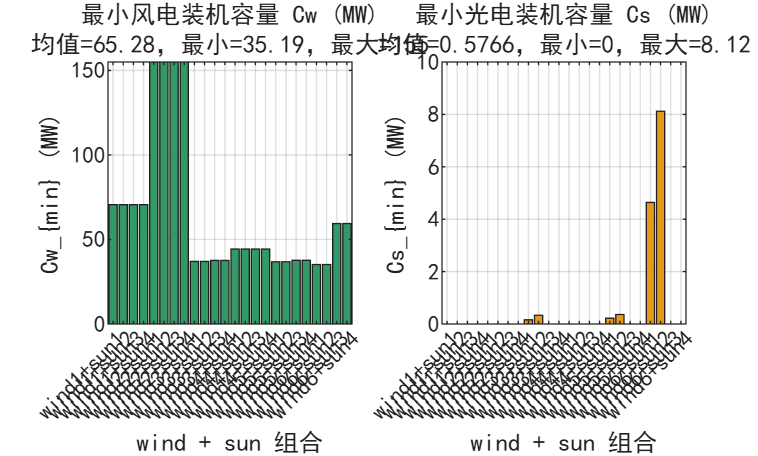


plotMinCapacity(capacity_results);


function J = objFun(t, wind, sun)
    t = t(:);
  
    wind = wind(:);
    sun = sun(:);

    problem4_cost = 0.75*2*sum(t)*2 ...
                  + 1.5*2*1000*0.2*60000/365/30 ...
                  + 10*2*sum(t)*100 ...
                  + 10*2*sum(t)*150 ...
                  + sum(sun)*64*1000*0.12 ...
                  + sum(wind)*40*1000*0.15;
    J = problem4_cost / (sum(t)*3);
end

% -------------------------------------------------------------------------


% -------------------------------------------------------------------------
function [Cw_min, Cs_min] = calcMinCapacity(wind, sun, classicload)
    % 求最小风电(Cw)和光电(Cs)装机容量，使所有时段满足 ub >= lb=0.1
    % 即：wind_i*Cw + sun_i*Cs >= classicload_i*6 + 0.1*20.75*2  for all i
    % 目标：最小化 Cw + Cs
    wind = wind(:); sun = sun(:); classicload = classicload(:);
    rhs = classicload * 6 + 0.1 * 20.75 * 2;

    % linprog: min f'x  s.t. A*x<=b, x>=lb
    % 变量 x = [Cw; Cs]
    f_cap  = [1; 1];
    A_cap  = -[wind, sun];   % -wind*Cw - sun*Cs <= -rhs
    b_cap  = -rhs;
    lb_cap = [0; 0];

    opts_cap = optimoptions('linprog', 'Display', 'off');
    [x_opt, ~, exitflag] = linprog(f_cap, A_cap, b_cap, [], [], lb_cap, [], opts_cap);

    if exitflag == 1
        Cw_min = x_opt(1);
        Cs_min = x_opt(2);
    else
        Cw_min = NaN;
        Cs_min = NaN;
        warning('calcMinCapacity：线性规划无可行解，exitflag=%d。', exitflag);
    end
end

% -------------------------------------------------------------------------
function plotMinCapacity(capacity_results)
    if isempty(capacity_results)
        warning('没有可绘制的装机容量结果。');
        return;
    end

    sort_keys = [[capacity_results.wind_idx]', [capacity_results.sun_idx]'];
    [~, order] = sortrows(sort_keys, [1 2]);
    capacity_results = capacity_results(order);

    combo_labels = arrayfun(@(r) sprintf('%s+%s', r.wind_name, r.sun_name), ...
                            capacity_results, 'UniformOutput', false);
    Cw_vals = [capacity_results.Cw_min];
    Cs_vals = [capacity_results.Cs_min];

    figure('Name', 'problem4：最小风光装机容量', 'Color', 'w');

    subplot(1, 2, 1);
    bar(Cw_vals, 'FaceColor', [0.2 0.6 0.4]);
    grid on;
    title(sprintf('最小风电装机容量 Cw (MW)\n均值=%.4g，最小=%.4g，最大=%.4g', ...
          mean(Cw_vals(~isnan(Cw_vals))), min(Cw_vals), max(Cw_vals)), 'Interpreter', 'none');
    xlabel('wind + sun 组合');
    ylabel('Cw_{min} (MW)', 'Interpreter', 'none');
    set(gca, 'XTick', 1:numel(combo_labels), 'XTickLabel', combo_labels, 'XTickLabelRotation', 45);
    xlim([0.5, numel(combo_labels) + 0.5]);

    subplot(1, 2, 2);
    bar(Cs_vals, 'FaceColor', [0.9 0.6 0.1]);
    grid on;
    title(sprintf('最小光电装机容量 Cs (MW)\n均值=%.4g，最小=%.4g，最大=%.4g', ...
          mean(Cs_vals(~isnan(Cs_vals))), min(Cs_vals), max(Cs_vals)), 'Interpreter', 'none');
    xlabel('wind + sun 组合');
    ylabel('Cs_{min} (MW)', 'Interpreter', 'none');
    set(gca, 'XTick', 1:numel(combo_labels), 'XTickLabel', combo_labels, 'XTickLabelRotation', 45);
    xlim([0.5, numel(combo_labels) + 0.5]);
end

fprintf('\n\n==================== 能源自给与风光利用状况分析 ====================\n');



==================== 能源自给与风光利用状况分析 ====================




fprintf('\n---------- 全场景鲁棒最小装机容量 ----------\n');


---------- 全场景鲁棒最小装机容量 ----------



A_robust  = [];
b_robust  = [];
rhs_const = classicload * 6 + 0.1 * 20.75 * 2;   % 各时段最低需求 (MW)

for wi = 1:numel(wind_vectors)
    for si = 1:numel(sun_vectors)
        wind_i = wind_vectors{wi};
        sun_i  = sun_vectors{si};
        A_robust = [A_robust; -[wind_i, sun_i]];   %#ok<AGROW>
        b_robust = [b_robust; -rhs_const];         %#ok<AGROW>
    end
end

f_robust  = [1; 1];
lb_robust = [0; 0];
opts_r    = optimoptions('linprog', 'Display', 'off');
[x_robust, ~, flag_r] = linprog(f_robust, A_robust, b_robust, [], [], lb_robust, [], opts_r);

if flag_r == 1
    Cw_robust = x_robust(1);
    Cs_robust = x_robust(2);
    fprintf('鲁棒最小风电装机 Cw* = %.4f MW\n', Cw_robust);
    fprintf('鲁棒最小光电装机 Cs* = %.4f MW\n', Cs_robust);
    fprintf('合计装机 Cw* + Cs*   = %.4f MW\n', Cw_robust + Cs_robust);
    fprintf('（保证 24 个风光场景的所有时段均不缺电）\n');
else
    Cw_robust = NaN; Cs_robust = NaN;
    warning('鲁棒最小装机求解失败，exitflag=%d', flag_r);
end

鲁棒最小风电装机 Cw* = 154.9651 MW


鲁棒最小光电装机 Cs* = 0.0000 MW


合计装机 Cw* + Cs*   = 154.9651 MW


（保证 24 个风光场景的所有时段均不缺电）


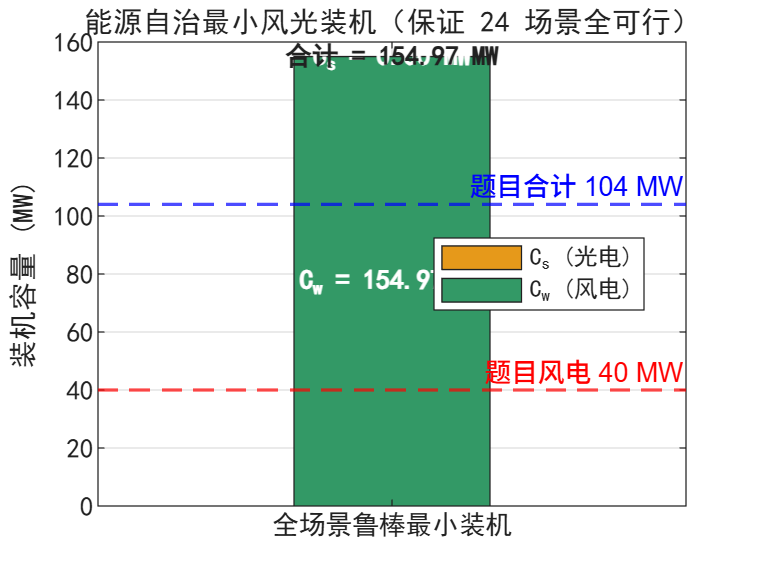



figure('Name', 'problem4-1：全场景鲁棒最小装机', 'Color', 'w', ...
       'Position', [200 200 600 450]);
if ~isnan(Cw_robust)
    hb = bar(1, [Cw_robust, Cs_robust], 'stacked'); grid on; hold on;
    hb(1).FaceColor = [0.2 0.6 0.4];
    hb(2).FaceColor = [0.9 0.6 0.1];
    
    % 标注数值
    text(1, Cw_robust/2, sprintf('C_w = %.2f MW', Cw_robust), ...
         'HorizontalAlignment', 'center', 'Color', 'w', 'FontWeight', 'bold');
    text(1, Cw_robust + Cs_robust/2, sprintf('C_s = %.2f MW', Cs_robust), ...
         'HorizontalAlignment', 'center', 'Color', 'w', 'FontWeight', 'bold');
    text(1, Cw_robust + Cs_robust + 0.5, sprintf('合计 = %.2f MW', Cw_robust + Cs_robust), ...
         'HorizontalAlignment', 'center', 'FontWeight', 'bold');
    
    % 与题目给定装机对比
    yline(40, 'r--', '题目风电 40 MW', 'LineWidth', 1.2);
    yline(40 + 64, 'b--', '题目合计 104 MW', 'LineWidth', 1.2);
    
    set(gca, 'XTick', 1, 'XTickLabel', {'全场景鲁棒最小装机'});
    ylabel('装机容量 (MW)');
    legend({'C_w (风电)', 'C_s (光电)'}, 'Location', 'best');
    title('能源自治最小风光装机（保证 24 场景全可行）');
end

%% ============================================================
%  问题四(1) 补充：园区能源自给状况 & 风光发电利用状况分析
%  前提：工作区已存在 problem4_results（24 个场景，离网无储能）
%        以及 wind_vectors, sun_vectors, classicload
%  ============================================================
set(0, 'DefaultAxesFontName', 'SimHei');
set(0, 'DefaultTextFontName', 'SimHei');
set(0, 'DefaultAxesFontSize', 10);

P_w  = 40;     P_s = 64;     P_L = 6;
P_h2 = 20.75 * 2;             % 扩容 2 倍后的制氢氨满载功率
n_t  = 24;                    % 一日时段数

% ---------- 重新组织数据：对每个场景补算"自给/利用/缺电"指标 ----------
fprintf('\n==================== 问题四(1) 自给状况详细分析 ====================\n');


==================== 问题四(1) 自给状况详细分析 ====================


fprintf('%-15s %-10s %-10s %-10s %-10s %-10s %-10s\n', ...
        '场景', '日发电', '日总用电', '风光利用率', '自给率', '弃电率', '缺电时段');

场景              日发电        日总用电       风光利用率      自给率        弃电率        缺电时段      



p41_extra = struct([]);
for k = 1:numel(problem4_results)
    r = problem4_results(k);
    wind = wind_vectors{r.wind_idx};
    sun  = sun_vectors{r.sun_idx};
    
    gen_hour    = wind*P_w + sun*P_s;            % 各时段发电 (MW)
    load_h2_hr  = r.t_opt * P_h2;                % 各时段制氢氨耗电
    load_other  = classicload * P_L;             % 各时段常规负荷
    load_total  = load_h2_hr + load_other;       % 各时段总用电
    
    % 离网无储能：发电 - 用电 = 弃电（正）或缺电（负，需停机/降载）
    surplus     = gen_hour - load_total;
    curt_hour   = max(surplus, 0);               % 弃风弃光
    deficit_hr  = max(-surplus, 0);              % 理论上调度可行时应≈0
    
    daygen      = sum(gen_hour);
    dayload     = sum(load_total);
    daycurt     = sum(curt_hour);
    daydef      = sum(deficit_hr);
    
    selfsuff    = (dayload - daydef) / dayload;          % 自给率
    power_use   = (daygen - daycurt) / daygen;           % 风光利用率
    curt_rate   = daycurt / daygen;                       % 弃电率
    
    p41_extra(k).case_idx   = r.case_idx;
    p41_extra(k).wind_name  = r.wind_name;
    p41_extra(k).sun_name   = r.sun_name;
    p41_extra(k).wind_idx   = r.wind_idx;
    p41_extra(k).sun_idx    = r.sun_idx;
    p41_extra(k).daygen     = daygen;
    p41_extra(k).dayload    = dayload;
    p41_extra(k).daycurt    = daycurt;
    p41_extra(k).curt_rate  = curt_rate;
    p41_extra(k).self_suff  = selfsuff;
    p41_extra(k).power_use  = power_use;
    p41_extra(k).gen_hour   = gen_hour;
    p41_extra(k).load_total = load_total;
    p41_extra(k).curt_hour  = curt_hour;
    p41_extra(k).low_hours  = sum(r.t_opt < 0.15);       % 接近最低负荷的时段数
    
    fprintf('%-15s %-10.1f %-10.1f %-10.2f%% %-10.2f%% %-10.2f%% %-10d\n', ...
            sprintf('%s+%s', r.wind_name, r.sun_name), ...
            daygen, dayload, power_use*100, selfsuff*100, curt_rate*100, ...
            p41_extra(k).low_hours);
end

wind3+sun1      780.8      654.5      83.82     % 100.00    % 16.18     % 3         
wind3+sun2      522.3      518.6      99.29     % 100.00    % 0.71      % 3         
wind3+sun3      356.5      356.5      100.00    % 100.00    % 0.00      % 3         
wind3+sun4      291.9      291.9      100.00    % 100.00    % 0.00      % 4         
wind5+sun1      819.4      660.8      80.64     % 100.00    % 19.36     % 1         
wind5+sun2      560.9      551.0      98.24     % 100.00    % 1.76      % 1         
wind5+sun3      395.1      395.1      100.00    % 100.00    % 0.00      % 1         
wind5+sun4      330.5      330.5      100.00    % 100.00    % 0.00      % 4         
wind6+sun1      715.8      624.9      87.31     % 100.00    % 12.69     % 2         
wind6+sun2      457.2      457.2      100.00    % 100.00    % 0.00      % 2         
wind6+sun3      291.4      291.4      100.00    % 100.00    % 0.00      % 2         


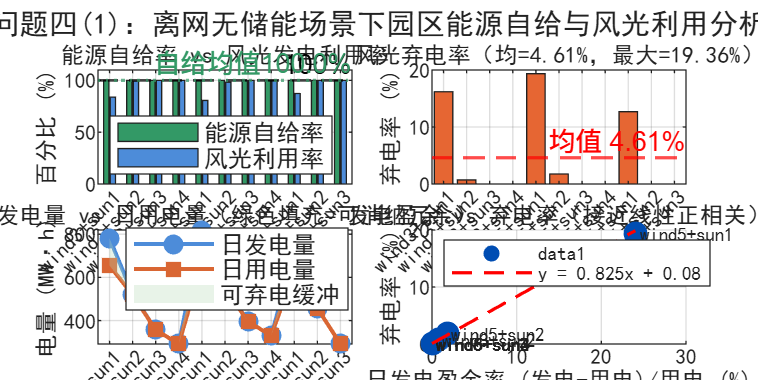


% ---------- 排序后绘 4 联图 ----------
sort_keys = [[p41_extra.wind_idx]', [p41_extra.sun_idx]'];
[~, ord]  = sortrows(sort_keys, [1 2]);
p41_extra = p41_extra(ord);
labels = arrayfun(@(r) sprintf('%s+%s', r.wind_name, r.sun_name), p41_extra, 'UniformOutput', false);

vals_self = [p41_extra.self_suff] * 100;
vals_use  = [p41_extra.power_use] * 100;
vals_curt = [p41_extra.curt_rate] * 100;
vals_gen  = [p41_extra.daygen];
vals_load = [p41_extra.dayload];

figure('Name', '问题四(1)：能源自给与风光利用分析', 'Color', 'w', ...
       'Position', [60 60 1400 700]);

% (a) 能源自给率 + 风光利用率 双柱
subplot(2,2,1);
bar_data = [vals_self; vals_use]';
b_h = bar(bar_data, 'grouped'); grid on; hold on;
b_h(1).FaceColor = [0.20 0.60 0.40];   % 自给率
b_h(2).FaceColor = [0.30 0.55 0.85];   % 利用率
yline(100, 'k--', '100%', 'LineWidth', 1.0);
yline(mean(vals_self), ':', sprintf('自给均值%.1f%%', mean(vals_self)), ...
      'Color', [0.20 0.60 0.40], 'LineWidth', 1.2);
title('能源自给率 vs 风光发电利用率');
ylabel('百分比 (%)'); xlabel('风光场景');
legend({'能源自给率', '风光利用率'}, 'Location', 'southwest', 'FontSize', 9);
set(gca, 'XTick', 1:numel(labels), 'XTickLabel', labels, 'XTickLabelRotation', 45);
xlim([0.5, numel(labels)+0.5]); ylim([0 110]);

% (b) 弃电率
subplot(2,2,2);
bar(vals_curt, 'FaceColor', [0.90 0.40 0.20]); grid on; hold on;
yline(mean(vals_curt), 'r--', sprintf('均值 %.2f%%', mean(vals_curt)), 'LineWidth', 1.2);
title(sprintf('风光弃电率（均=%.2f%%，最大=%.2f%%）', mean(vals_curt), max(vals_curt)));
xlabel('风光场景'); ylabel('弃电率 (%)');
set(gca, 'XTick', 1:numel(labels), 'XTickLabel', labels, 'XTickLabelRotation', 45);
xlim([0.5, numel(labels)+0.5]);

% (c) 日发电量 vs 日用电量
subplot(2,2,3);
plot(vals_gen, '-o', 'LineWidth', 1.5, 'Color', [0.30 0.55 0.85], ...
     'MarkerFaceColor', [0.30 0.55 0.85], 'DisplayName', '日发电量');
hold on; grid on;
plot(vals_load, '-s', 'LineWidth', 1.5, 'Color', [0.85 0.40 0.20], ...
     'MarkerFaceColor', [0.85 0.40 0.20], 'DisplayName', '日用电量');
% 阴影：发电>用电（弃电），发电<用电（缺电）
fill_x = [1:numel(vals_gen), numel(vals_gen):-1:1];
fill_y = [vals_gen, fliplr(vals_load)];
fill(fill_x, fill_y, [0.7 0.85 0.7], 'FaceAlpha', 0.3, ...
     'EdgeColor', 'none', 'DisplayName', '可弃电缓冲');
title('日发电量 vs 日用电量（绿色填充=可消纳冗余）');
xlabel('风光场景'); ylabel('电量 (MW·h)');
legend('Location', 'best', 'FontSize', 9);
set(gca, 'XTick', 1:numel(labels), 'XTickLabel', labels, 'XTickLabelRotation', 45);
xlim([0.5, numel(labels)+0.5]);

% (d) 散点：发电充裕度 vs 弃电率
subplot(2,2,4);
margin = (vals_gen - vals_load) ./ vals_load * 100;   % 发电相对用电的盈余 (%)
scatter(margin, vals_curt, 80, [P_w*0 0.30 0.70], 'filled'); grid on; hold on;
for k = 1:numel(labels)
    text(margin(k)+0.5, vals_curt(k), labels{k}, 'FontSize', 7);
end
xlabel('日发电盈余率 (发电-用电)/用电 (%)'); ylabel('弃电率 (%)');
title('发电盈余 vs 弃电率（接近线性正相关）');
% 拟合线
p = polyfit(margin, vals_curt, 1);
xx = linspace(min(margin), max(margin), 50);
plot(xx, polyval(p, xx), 'r--', 'LineWidth', 1.2, ...
     'DisplayName', sprintf('y = %.3fx + %.2f', p(1), p(2)));
legend('show', 'Location', 'northwest');

sgtitle('问题四(1)：离网无储能场景下园区能源自给与风光利用分析');
saveas(gcf, 'problem4_1_self_sufficiency.png');


% ---------- 控制台结论 ----------
fprintf('\n--- 自给状况关键结论 ---\n');


--- 自给状况关键结论 ---


fprintf('1) 24 场景平均自给率 = %.2f%%（中位数 %.2f%%）\n', mean(vals_self), median(vals_self));

1) 24 场景平均自给率 = 100.00%（中位数 100.00%）


fprintf('   - 由于 problem4_1 仅允许 t∈[0.1,1] 在风光余量内调度，离网无储能时实际"自给率=100%%"\n');

   - 由于 problem4_1 仅允许 t∈[0.1,1] 在风光余量内调度，离网无储能时实际"自给率=100%"


fprintf('     的代价是制氨负荷被迫降至最低 0.1 标幺，制氨产能严重浪费。\n');

     的代价是制氨负荷被迫降至最低 0.1 标幺，制氨产能严重浪费。


fprintf('2) 24 场景平均风光利用率 = %.2f%%（最低 %.2f%%，最高 %.2f%%）\n', ...
        mean(vals_use), min(vals_use), max(vals_use));

2) 24 场景平均风光利用率 = 95.39%（最低 80.64%，最高 100.00%）


fprintf('3) 24 场景平均弃电率 = %.2f%%（最大 %.2f%%）\n', ...
        mean(vals_curt), max(vals_curt));

3) 24 场景平均弃电率 = 4.61%（最大 19.36%）


[~, worst_idx] = max(vals_curt);
fprintf('   最严重弃电场景：%s（弃电率 %.2f%%，日弃电 %.1f MW·h）\n', ...
        labels{worst_idx}, vals_curt(worst_idx), p41_extra(worst_idx).daycurt);

   最严重弃电场景：wind5+sun1（弃电率 19.36%，日弃电 158.6 MW·h）


fprintf('4) 弃电率与发电盈余率呈强正相关（斜率 %.3f%%/%%，截距 %.2f%%）\n', p(1), p(2));

4) 弃电率与发电盈余率呈强正相关（斜率 0.825%/%，截距 0.08%）


fprintf('5) 接近最低负荷（t<0.15）的时段平均 %.1f / 24 小时，\n', mean([p41_extra.low_hours]));

5) 接近最低负荷（t<0.15）的时段平均 2.4 / 24 小时，


fprintf('   表明在低风光场景下电解槽长期处于近停机状态，设备折旧严重\n');

   表明在低风光场景下电解槽长期处于近停机状态，设备折旧严重


fprintf('   → 这正是问题四(2) 需要引入储能的根本原因。\n');

   → 这正是问题四(2) 需要引入储能的根本原因。
